clc; clear all; close all;

k1 = 400000;
k2 = 210000;
k3 = 200000;
b1 = 8000;
b2 = 4000;
b3 = 2000;
m1 = 435;
m2 = 278;
m3 = 204;

A = [0 0 0 1 0 0;
     0 0 0 0 1 0;
     0 0 0 0 0 1;
     (-k1-k2-k3)/m1 k2/m1 k3/m1 (-b1-b2-b3)/m1 b2/m1 b3/m1;
     k2/m2 -k2/m2 0 b2/m2 -b2/m2 0;
     k3/m3 0 -k3/m3 b3/m3 0 -b3/m3]

A =                          0                         0                         0                         1                         0                         0
                         0                         0                         0                         0                         1                         0
                         0                         0                         0                         0                         0                         1
         -1862.06896551724          482.758620689655          459.770114942529          -32.183908045977          9.19540229885057          4.59770114942529
          755.395683453237         -755.395683453237                         0          14.3884892086331         -14.3884892086331                         0
          980.392156862745                         0         -980.392156862745          9.80392156862745                         0         -9.80392156862745



[D, V] = eig(A);

r = diag(V)

r =           -18.8482152004452 +      44.5712277751096i
          -18.8482152004452 -      44.5712277751096i
          -6.25251937590678 +      29.1750745163041i
          -6.25251937590678 -      29.1750745163041i
          -3.08742483526678 +      17.8073223040438i
          -3.08742483526678 -      17.8073223040438i



y_initial = [1100e-3 500e-3 500e-3 0.05 0.05 0.05]'

y_initial =                        1.1
                       0.5
                       0.5
                      0.05
                      0.05
                      0.05



c = inv(D)*y_initial;

simTime = 1.5;
t = 0;
idx = 1;
dt = 10^-5;
y = 0;

while(t <= simTime)
    y = 0;
    for j = 1:6
    y = y + c(j) *D(: ,j)* exp (r(j)*t);
    end

    t_plt(idx) = t;
    x1_plt(idx) = y(1);
    x2_plt(idx) = y(2);
    x3_plt(idx) = y(3);
    x1Dot_plt(idx) = y(4);
    x2Dot_plt(idx) = y(5);
    x3Dot_plt(idx) = y(6);


    t = t + dt;
    idx = idx + 1;
end

plot(t_plt, x1_plt)

hold on
plot(t_plt, x2_plt)

plot(t_plt, x3_plt)

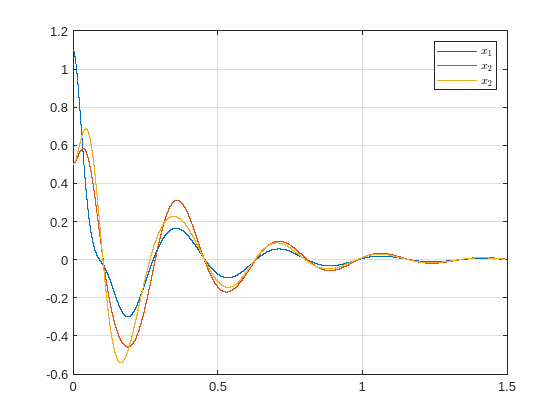

grid
legend("$x_1$","$x_2$","$x_2$", 'Interpreter','latex')

hold off


plot(t_plt, x1Dot_plt)

hold on
plot(t_plt, x2Dot_plt)

plot(t_plt, x3Dot_plt)

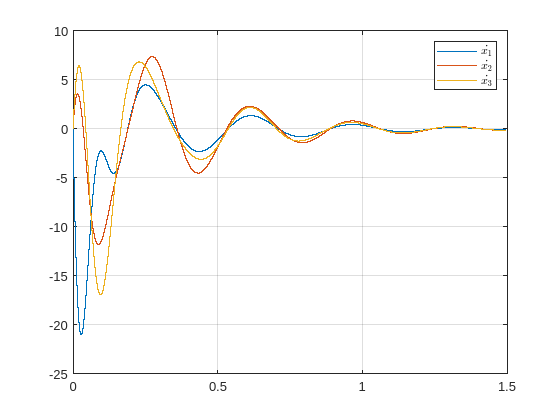

grid
legend("$\dot{x_1}$","$\dot{x_2}$","$\dot{x_3}$", 'Interpreter','latex')


x1 = 1100e-3;
x1dot = 0.05;
x2 = 500e-3;
x2dot = 0.05;
x3 = 500e-3;
x3dot = 0.05;

t = 0;
endtime = 1.5;
i = 1;

while t < endtime
        
        dx1 = x1;
        dx2 = x2-x1;
        dx3 = x3-x1;
        dx1dot = x1dot;
        dx2dot = x2dot - x1dot;
        dx3dot = x3dot - x1dot;

        fk1 = k1*dx1;
        fb1 = b1*dx1dot;
        fk2 = k2*dx2;
        fb2 = b2*dx2dot;
        fk3 = k3*dx3;
        fb3 = b3*dx3dot;

       
        x1dotdot = (-fk1-fb1+fk2+fb2+fk2+fb3)/m1;
        x2dotdot = (-k2*dx2-b2*dx2dot)/m2;
        x3dotdot = (-k3*dx3-b3*dx3dot)/m3;

        timeplot(i) = t;
        x1plot(i) = x1;
        x2plot(i) = x2;
        x3plot(i) = x3; 
        x1dotplot(i) = x1dot;
        x2dotplot(i) = x2dot;
        x3dotplot(i) = x3dot;
        
        
        x1dot = x1dot + x1dotdot*dt;
        x2dot = x2dot + x2dotdot*dt;
        x3dot = x3dot + x3dotdot*dt;

        x1 = x1 + x1dot*dt;
        x2 = x2 + x2dot*dt;
        x3 = x3 + x3dot*dt;


        t = t + dt;
        i = i + 1;
end

figure
plot(timeplot,x1plot, 'r')
hold on 
plot(timeplot,x2plot, 'b')
plot(timeplot,x3plot, 'g')
plot(t_plt, x1_plt, '--r')

plot(t_plt, x2_plt, '--b')

plot(t_plt, x3_plt, '--g')

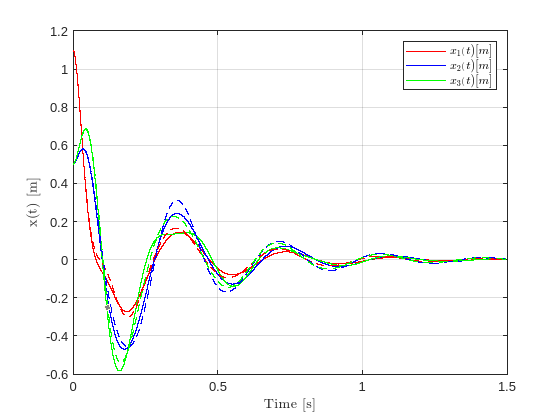

grid
legend("$x_1(t) [m]$", "$x_2(t) [m]$", "$x_3(t) [m]$", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("x(t) [m]", 'Interpreter', 'latex')

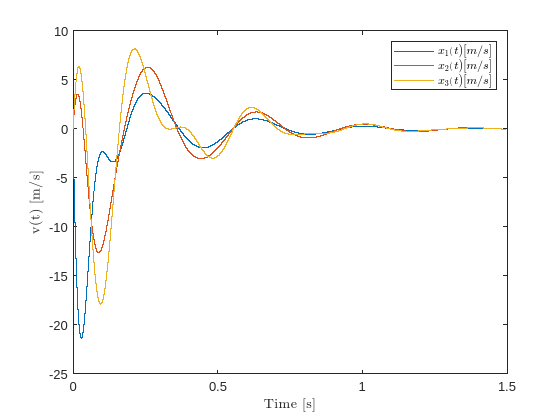


figure
plot(timeplot,x1dotplot)
hold on 
plot(timeplot,x2dotplot)
plot(timeplot,x3dotplot)
legend("$x_1(t) [m/s]$", "$x_2(t) [m/s]$", "$x_3(t) [m/s]$", 'Interpreter', 'latex')
xlabel("Time [s]", 'Interpreter', 'latex')
ylabel("v(t) [m/s]", 'Interpreter', 'latex')